# Direct Stiffness Space Frame Analysis

This script file uses the Direct Stiffness Method to analyze a space truss structure.

It loads data from the **StructureData.m** file, performs the analysis, and displays the results.

Close all existing figure windows, clear workspace variables, and clear the command window

close all; clearvars; clc;


Load Structure Data from StructureData.m file

StructureData

Perform space frame analysis using Direct Stiffness Method

The function **space_frame_analysis** takes nodes and members matrices as input arguments

It returns displacement for the structure node

**Note: **reactions, internal forces, stress, and strain vectors for the structure will be implemented in future versions

[displacement] = space_frame_analysis(nodes, members);

## Display results

### Displacement of each DOF

disp('Displacement of each DOF:');

Displacement of each DOF:




n = size(nodes,1);

% Pre-allocate the cell array
rowLabels = cell(1, n);

% Loop through the elements and generate the cell array
for i = 1:n
    rowLabels{i} = sprintf('Node %d', i);
end
reshapedDisp = reshape(displacement,6,n)';
displacementable = table(reshapedDisp(:,1), ...
    reshapedDisp(:,2),...
    reshapedDisp(:,3),...
    reshapedDisp(:,4),...
    reshapedDisp(:,5),...
    reshapedDisp(:,6),...
    'VariableNames',{'u' 'v' 'w' 'phi' 'theta' 'psi'},...
    'RowNames',rowLabels)

displacementable = 4×6 table
                  u             v             w            phi          theta           psi    
              __________    _________    ___________    __________    __________    ___________

    Node 1             0            0              0             0             0              0
    Node 2     0.0058977    0.0018175    -2.5762e-05     -0.004291     0.0012827      0.0023957
    Node 3    4.3771e-06    0.0018113      -0.017399    -0.0043268    -0.0052196    -0.00037143
    Node 4             0            0              0             0             0              0


## Plots

Set Displacement Scale Factor and Add displacements to nodes.

DSF = 20; %  Displacement Scale Factor is only for visual purposes.
displaced_nodes = [nodes(:,1:3)+ DSF*reshapedDisp(:,1:3)];

Plot Original Structure

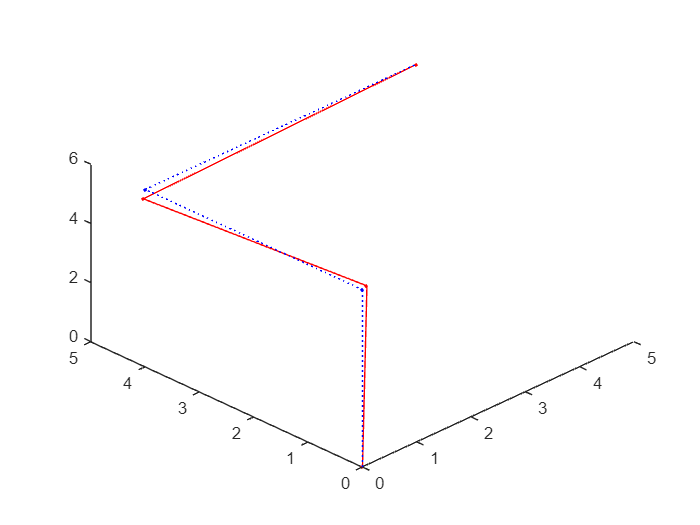

figure
hold on;

for i=1:size(members,1)
    n1 = members(i,1); %node 1 index
    n2 = members(i,2); %node 2 index
    X = [nodes(n1,1) nodes(n2,1)];
    Y = [nodes(n1,2) nodes(n2,2)];
    Z = [nodes(n1,3) nodes(n2,3)];
    plot3(X,Y,Z,"b.:")
    X = [displaced_nodes(n1,1) displaced_nodes(n2,1)];
    Y = [displaced_nodes(n1,2) displaced_nodes(n2,2)];
    Z = [displaced_nodes(n1,3) displaced_nodes(n2,3)];
    plot3(X,Y,Z,"r.-")
end
view(-45,45)

## Work in progress

% % Reactions at constrained nodes (N and Nm)
% disp('Reactions at constrained nodes (N and Nm):');
% disp(reactions);
% 
% % Internal forces in each member (N and Nm)
% disp('Internal forces in each member (N and Nm):');
% disp(internalForces);
% 
% % Stress in each member (Pa)
% disp('Stress in each member (Pa):');
% disp(stress);
% 
% % Strain in each member
% disp('Strain in each member:');
% disp(strain);

% This script loads the structure data, performs the space frame analysis, and displays the displacement, reactions, internal forces, stress, and strain results for each node and member.
% The actual implementation of the Direct Stiffness Method is contained within the space_frame_analysis function (not provided here).